## Frequency Analysis

#### General parameters 

These are the same 'options' used for the filtering and segmentation

clearvars

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

addpath('./FreqFeatures')
data = importdata("../physionet.org/segmented_data/3000063_0006-0005.txt");

[f, fftABP] = singlesidedFFT(data(:,1), data(:,2), 1);

[~, fftPPG] = singlesidedFFT(data(:,1), data(:,3), 1);

df = mean(diff(f))

df = 0.0305

Fs = df*(length(f)*2)

Fs = 125.0000

dT = 1/Fs

dT = 0.0080

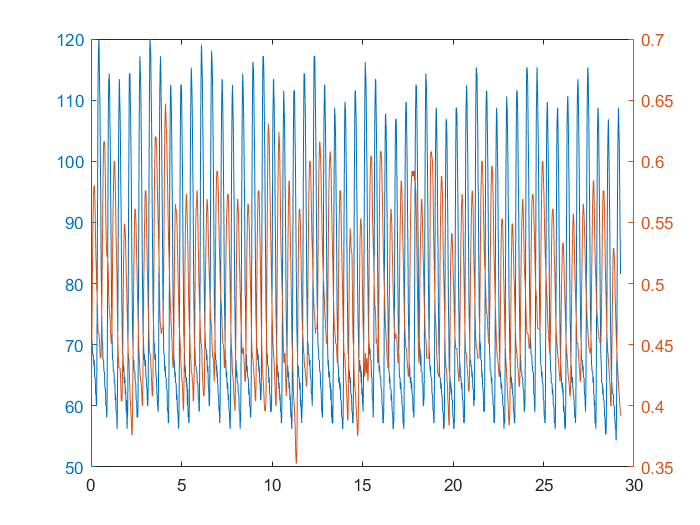


figure;
yyaxis left
plot(data(:,1), data(:,2))
hold on;
yyaxis right
plot(data(:,1), data(:,3))
hold off

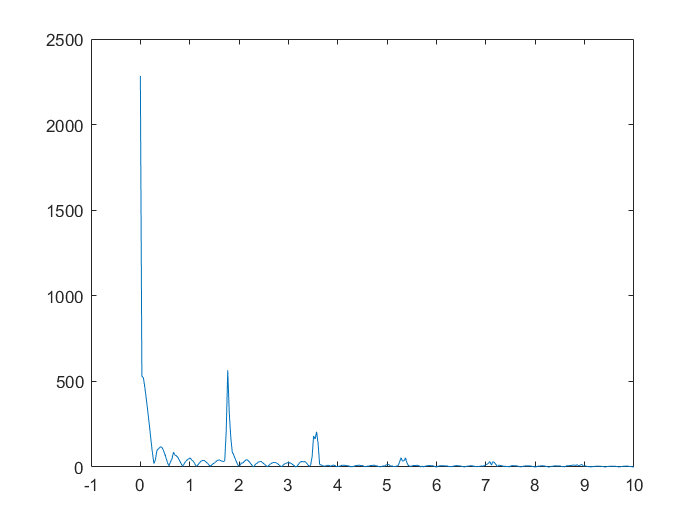


figure;
plot(f, abs(fftABP))
xlim([-1 10])

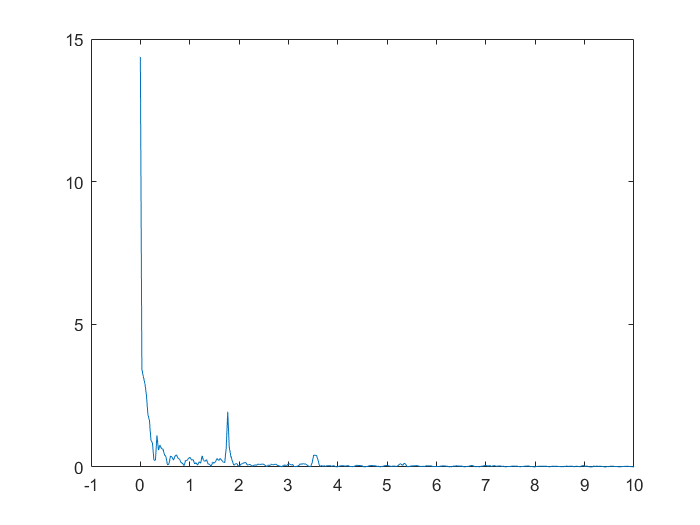

figure;
plot(f, abs(fftPPG))
xlim([-1 10])


psdABP = (abs(fftABP)).^2;
psdABP(2:end) = psdABP(2:end)/2;

psdPPG = (abs(fftPPG)).^2;
psdPPG(2:end) = psdPPG(2:end)/2;

% 
% figure;
% plot(f1, abs(psdABP))
% xlim([-1 10])
% figure;
% plot(f1, abs(psdPPG))
% xlim([-1 10])


### Method 1

Extract DC and 100 (or X) most powerful frequencies and reconstruct the ABP using these frequencies.

% Extract DC + 100 most powerful freqs

maximaIndices = [1; extractMaxFreqSpectrum(abs(fftABP), 100, 1)]

Unrecognized function or variable 'extractMaxFreqSpectrum'.


recon_fftABP = zeros(size(fftABP));
recon_fftABP(maximaIndices) = fftABP(maximaIndices);

[recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);

plot(f, abs(recon_fftABP))
xlim([-1 10])

plot(recon_time, recon_ABP)
ylim([40 120])
plot(data(:,1), data(:,2))


### Method 2

Determine which frequency components make up 99% (or X %) of the signal, and reconstruct the ABP using these frequency components.

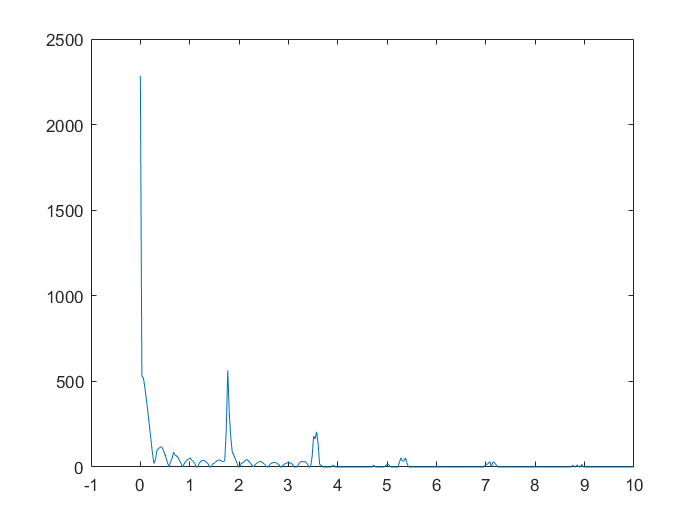

% get 99.9% of power components
maximaIndices = getPowerContributors(psdABP, 99.9);

recon_fftABP = zeros(size(fftABP));
recon_fftABP(maximaIndices) = fftABP(maximaIndices);

[recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);

recon_time(length(data)+1:end) = [];
recon_ABP(length(data)+1:end) = [];

plot(f, abs(recon_fftABP))
xlim([-1 10])

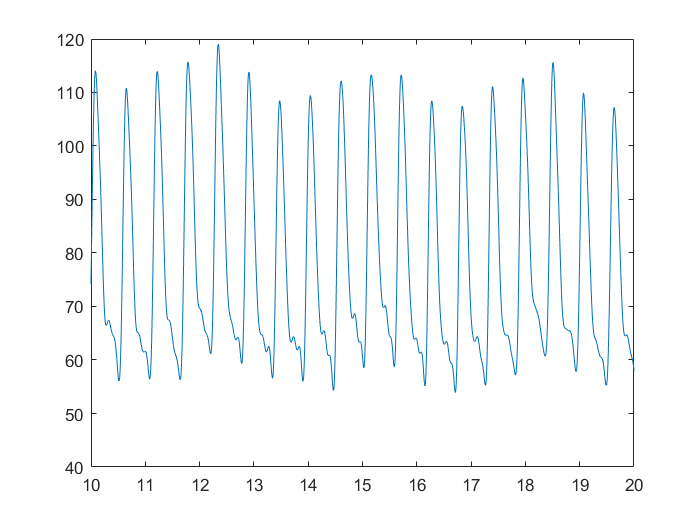


recon_ABP = lowpass(recon_ABP, 8, 125);

plot(recon_time, recon_ABP)
ylim([40 120])
xlim([10 20])

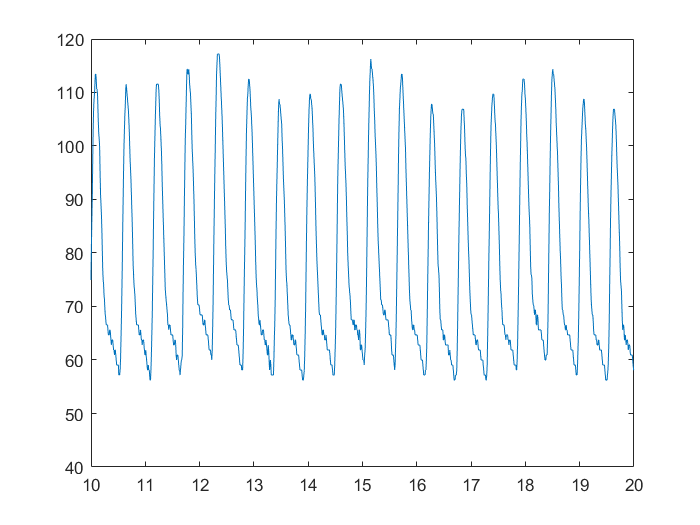

plot(data(:,1), data(:,2))
ylim([40 120])
xlim([10 20])


cost_sse = sum((recon_ABP - data(:,2)).^2)

cost_sse = 1.7193e+04

cost_mse = cost_sse/length(data)

cost_mse = 4.7000

### Method 3

Divide the frequency spectrum into a number of "frequency bins", for example, 1 Hz wide. The most significant frequencies within each of these bins are then extracted and used to reconstruct the ABP waveform.

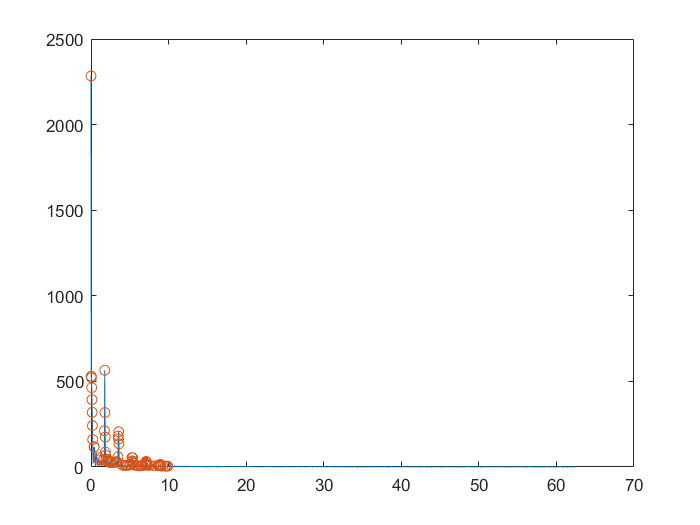

% use frequency bins
indices = getMaxFreqsInBins(f, abs(fftABP), 10, 1, 10);

recon_fftABP = zeros(size(fftABP));
recon_fftABP(indices) = fftABP(indices);

plot(f, abs(fftABP));
hold on;
scatter(f(indices), abs(fftABP(indices)))
hold off;

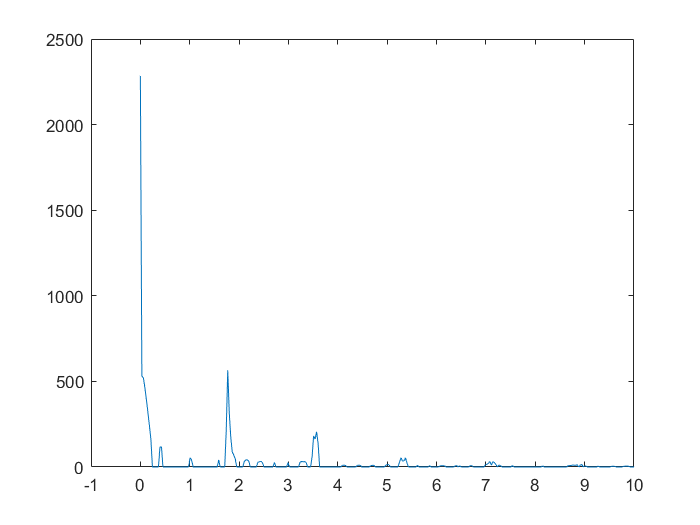


[recon_time, recon_ABP] = singlesidedIFFT(f, recon_fftABP);

recon_time(length(data)+1:end) = [];
recon_ABP(length(data)+1:end) = [];

plot(f, abs(recon_fftABP))
xlim([-1 10])

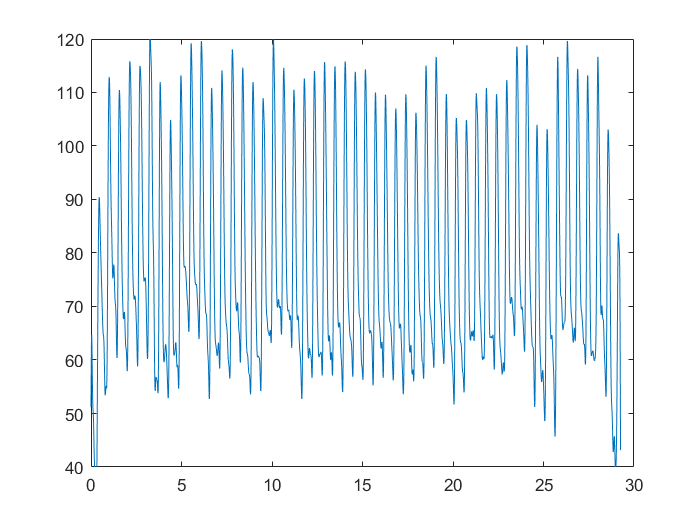


%recon_ABP = lowpass(recon_ABP, 8, 125);

plot(recon_time, recon_ABP)
ylim([40 120])

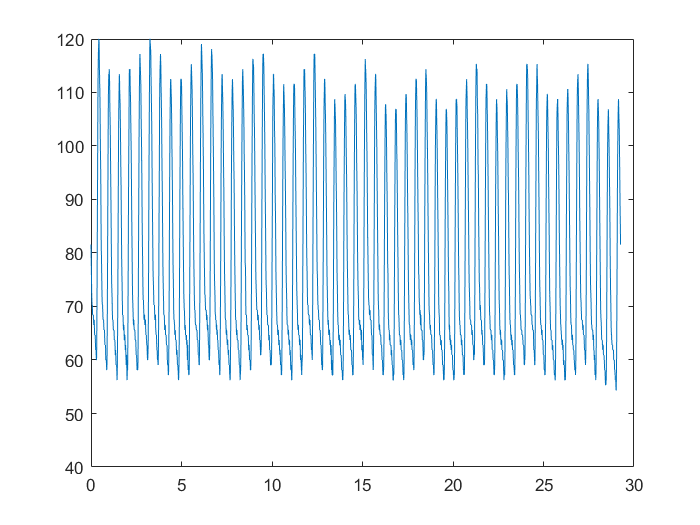

%xlim([10 20])
plot(data(:,1), data(:,2))
ylim([40 120])

%xlim([10 20])

cost_sse = sum((recon_ABP - data(:,2)).^2)

cost_sse = 1.5032e+05

cost_mse = cost_sse/length(data)

cost_mse = 41.0943

### Using a transfer function approach

tol = 1e-3;

fftABP(abs(fftABP) < tol) = 0;

fftPPG(abs(fftPPG) < tol) = 0;

transFunc = fftABP/fftPPG;

plot(f, abs(transFunc))
title("Transfer Function")

[tf_time, tf] = singlesidedIFFT(f, transFunc);
plot(tf_time, tf)